# Week 2 Demo - creating and plotting functions

Consider a function $f(x)$.  In this demo, I will cover ways to plot $f$ versus $x$.

## Approach 1: element-wise arithmetic with vectors

Let us create a vector $x$ with 100 points spanning from 0 to 5.  Suppose one wanted to plot $e^x$, they would do so in the following manner:

x = linspace(0,5,100);
y = exp(x);

y =     1.0000    1.0518    1.1063    1.1636    1.2239    1.2873    1.3540    1.4241    1.4979    1.5755    1.6571    1.7429    1.8332    1.9282    2.0280    2.1331    2.2436    2.3598    2.4821    2.6106    2.7459    2.8881    3.0377    3.1951    3.3606    3.5347    3.7178    3.9104    4.1130    4.3260    4.5501    4.7858    5.0337    5.2945    5.5688    5.8572    6.1606    6.4798    6.8154    7.1685    7.5398    7.9304    8.3412    8.7733    9.2278    9.7058   10.2086   10.7374   11.2937   11.8787


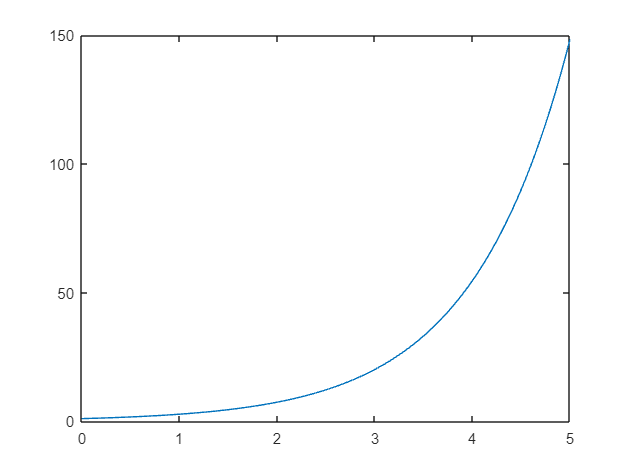

figure 
plot(x,y)
title('f(x)=e^x')

xlabel('x)')
ylabel('y')



Suppose now you wanted to plot $f(x)=x e^x$.  Let us try:

% z = x*y
% uncomment the above line of code to see an error message

Notice right away we get an error.  What happened?  Well, it is important to recall that $x$ and $y$ are row vectors  Multiplication of two row vectors has no mathematical meaning.  **Aside:** multiplying a row vector times a column vector is like taking the dot-product of the two vectors, and multiplying a column vector by a row vector creates a matrix.

What we really want to do is plot a vector of $f(x)$ values versus a vector of $x$ values.  To do so, we evaluate $f(x)$ *element-wise *by putting a "." before the multiplication operation:

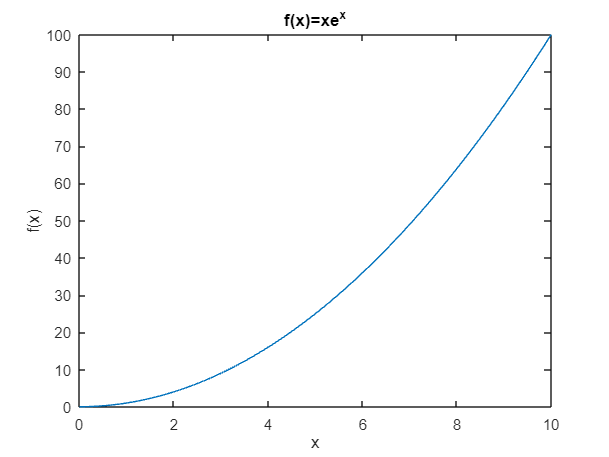

z = x.*y;
figure
plot(x,z)
title('f(x)=xe^x')
xlabel('x')
ylabel('f(x)')

Note the use of Latex in the labeling and throughout this document.  While not a requirement, the font and syntax of Latex are commonplace for scientific writing and can help make your documents look more elegant.  We will learn some of the basics later on, and if you are curious there are countless resources online.

## Approach 2: "Anonymous Functions"

There is another way to plot functions, which is arguably more elegant.  Consider for example $\exp{x}$.  When calling this function in our code, we are really evaluating a built-in function at one or many points in a vector, $x$.  There is a way in matlab to create our own such functions:

% f = @ (x) won't work since you need account for element-wise peration
f = @(x)x.*exp(x)

We have created our own function handle.  Note that we include the "." before the multiplication symbol.  This is a very important detail, since **we want to be able to input vectors into our function**.  Now, to plot, it is quite straightforward:

plot(x,f(x))
title('f(x) = xe^x')
xlabel('x')
ylabel('f(x)')

We can also plot $x^2$ and $20\frac{x}{e^x}$ in similar manners:

g = @(x) x.^2

g = function_handle with value:
    @(x)x.^2


h = @(x) 20*x./exp(x)

h = function_handle with value:
    @(x)20*x./exp(x)


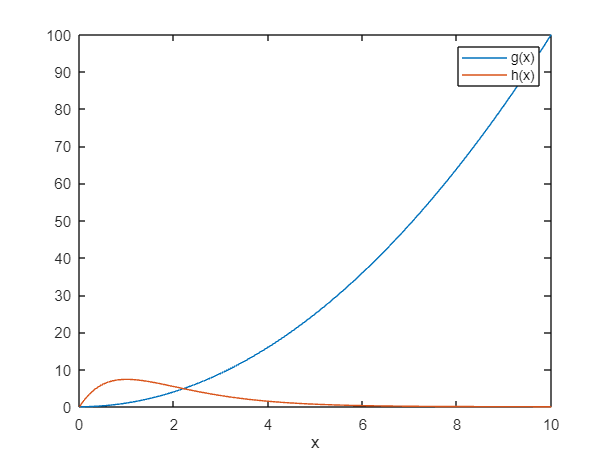

figure 
plot(x,g(x))
hold on
plot(x, h(x))
legend('g(x)', 'h(x)')
xlabel('x')

To plot multiple curves on the same plot, one must enter "`hold on" `in between the lines which plot the curves`.  `Note that when defining $h(x)$, we do not need to use element-wise multiplication with the scalar value $20$.  As you learned in Calc 3, multiplying a vector by a scalar is well-defined mathematically.  Also note the addition of a legend, which will come in handy later on.  